# Direct Yaw Control - Development workflow 

#### Lucas A. R. Raimundo 

#### Universidade de Brasília 

#### ESC SIM

Clear the variables, and Command Window

clear; clc;

Add the VI-CRT Path, and the Model's Path to the top of the search path for the current MATLAB session

% ADD FOLDERS TO PATH (VICRT WORKING DIR, and DYC MODEL)
addpath('C:\Users\lucas\Desktop\working_dir\','D:\working\23dofmodels\advanced_vdc\');

Add the Path to the send files genreated by VI-CRT used in the co-simulation, and Vehicle's data Path

path_send = 'C:\Users\lucas\Desktop\working_dir\';
path_vehicledata = 'C:\Users\lucas\Desktop\PPMEC_2023\2261_data\Maneuvers Data 226 T4\';

Select the desired Maneuver to set the correspondent co-simulation send file, and the data file acquired in the vehicle

Display the variables vicrt_inputfile, and vehicle_data to double check the information

maneuver = 'RAMP_RH12002';
run('select_maneuver_files.m');
vicrt_inputfile

vicrt_inputfile = 'C:\Users\lucas\Desktop\working_dir\2261_VOLCANO_ramp_RH12002_send_svm.xml'

vehicle_data

vehicle_data = 'C:\Users\lucas\Desktop\PPMEC_2023\2261_data\Maneuvers Data 226 T4\05 - Steering Ramp\TO120SISRH_0002.csv'

Running the co-simluation

The warnings are disabled

w = warning('off','all');
sim_CRT = sim('D:\working\23dofmodels\advanced_vdc\vdc_dyc_v3.slx');


Event data is being read from input XML file...

Aerodynamic force inactive or non-existent. Skipped.
Initializing powertrain / driveline...
Done.

Initializing tires...
Loading road data file... (file=C:/Users/lucas/Desktop/flat_085.rdf)

road file total reading time = 0.001s

FLAT road model has been initialized...

Done.

Initializing driver...

Done.

-- INFO -- VI-CarRealTime: IO Bus for 'C:\Users\lucas\Desktop\working_dir\2261_VOLCANO_ramp_RH12002_send_svm.xml' loaded.

=            VI-CarRealTime            =
  VERSION : 20.2
  REVISION: 51012//tags/release/20/20.2/RTM/software
  BUILT ON: phoenix/04-Feb-21


 Using Simulation File: C:\Users\lucas\Desktop\working_dir\2261_VOLCANO_ramp_RH12002_send_svm.xml

Event data is being read from input XML file...

Aerodynamic force inactive or non-existent. Skipped.
Performing the simulation: 2261_VOLCANO_ramp_RH1200

warning(w);

Import Vehicle data

run('import_vehicle_data.m');

Create the simlution variables generated by the co-simulation

run('vicrtsim_to_data.m');

Calculate the time difference to correlate the co-simulation results to the vehicle data

run('calculate_correlation_time.m');

Calulate the ESC activation time (for both the co-simluation, and the vehicle data)

run('esc_actv_time.m');

Display and save the results 

Note: Check and adjust the results' Path in "plot_results.m" code

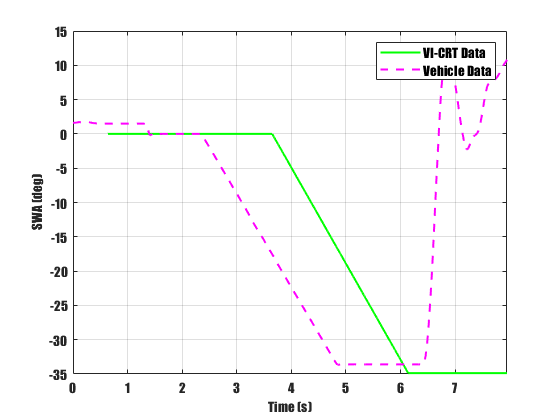

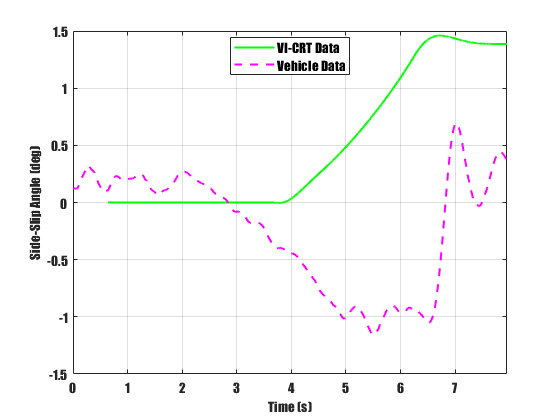

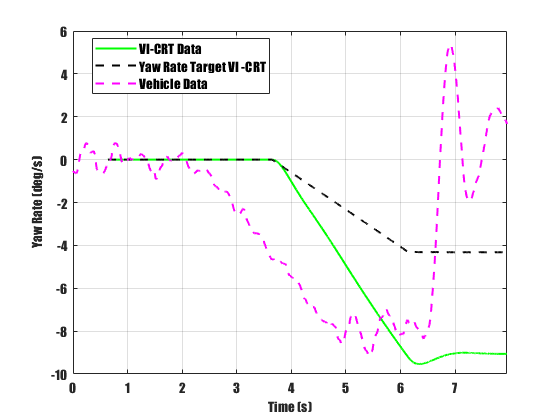

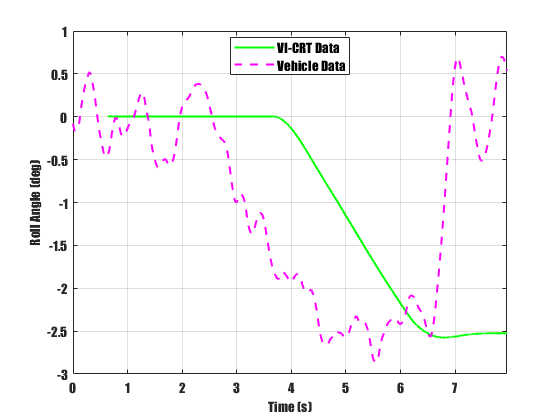

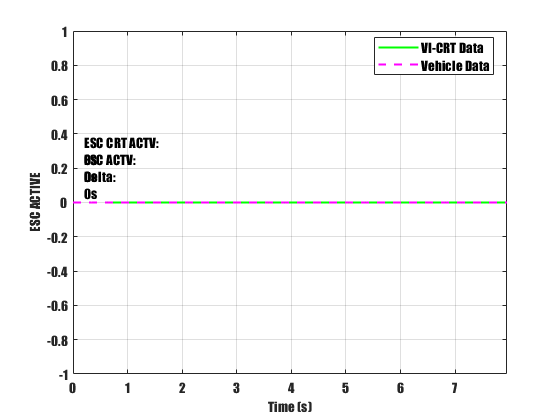

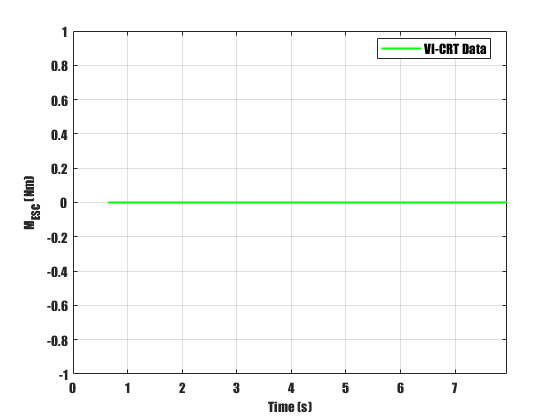

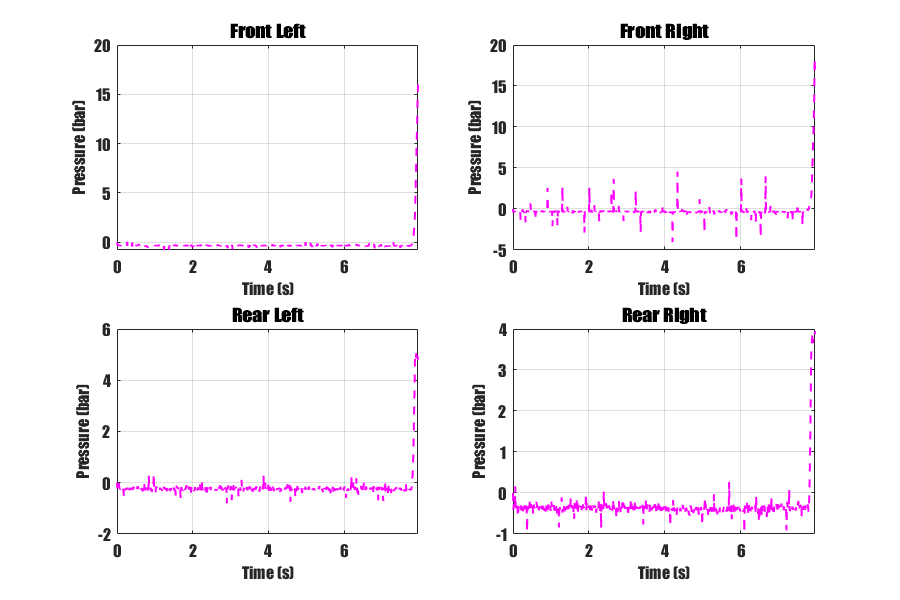

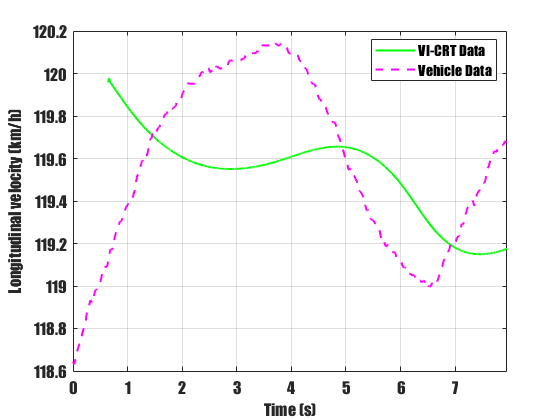

run('plot_results.m');